Dataset: TSVD


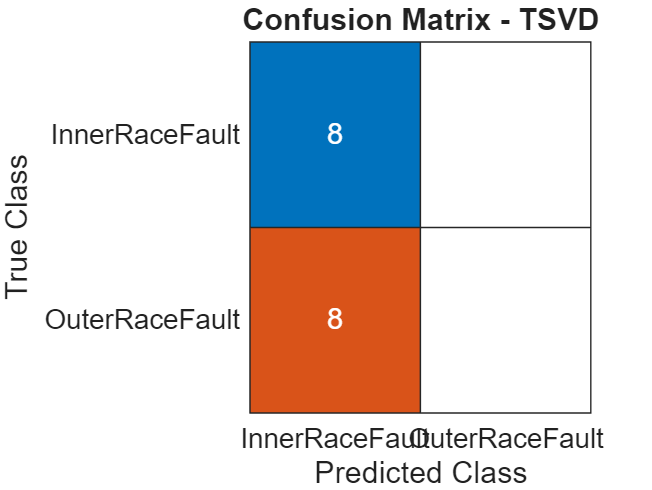

Accuracy: 0.5000


Dataset: RSVD


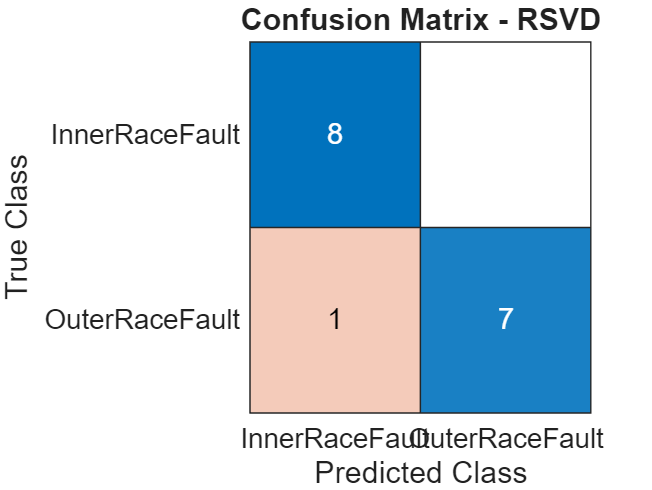

Accuracy: 0.9375


Dataset: WSSVD


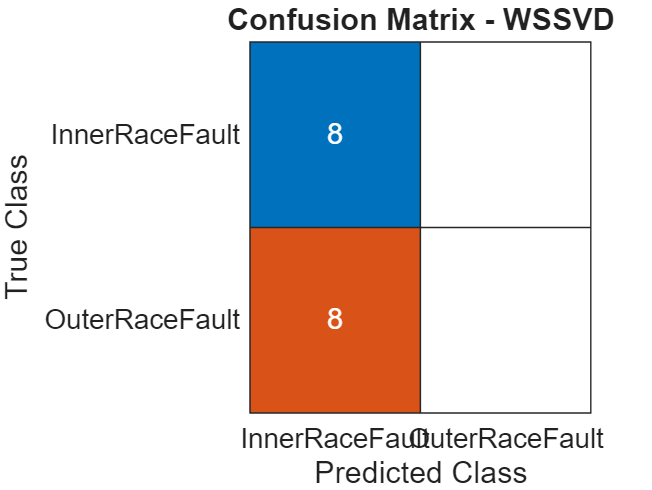

Accuracy: 0.5000


Dataset: WNNM


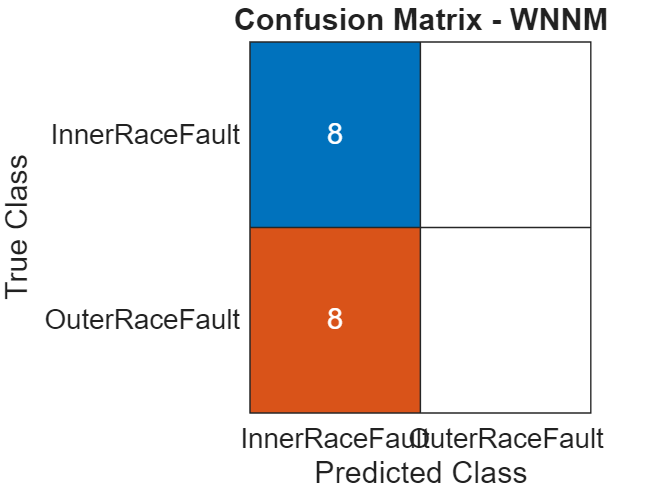

Accuracy: 0.5000


%% ============================================================
% BEARING FAULT CLASSIFICATION (LEAKAGE FREE)
% Random Forest + File-Level Split
% ============================================================

clc
clear
close all

%% ROOT DIRECTORY

root = "C:\Users\chara\OneDrive\Desktop\IMS\train_data\";

datasets = {
root + "TSVD_signals"
root + "RSVD_signals"
root + "WSSVD_signals"
root + "WNNM_signals"
};

dataset_names = {
"TSVD"
"RSVD"
"WSSVD"
"WNNM"
};

segment_length = 200;
overlap = 100;

%% ============================================================

for d = 1:length(datasets)

folder = datasets{d};

fprintf('\n=================================\n')
fprintf('Dataset: %s\n',dataset_names{d})
fprintf('=================================\n')

files = dir(fullfile(folder,'*.mat'));

%% ---------- FILE LABELS ----------

file_labels = strings(length(files),1);

for i = 1:length(files)

fname = lower(files(i).name);

if contains(fname,"baseline")
file_labels(i) = "Baseline";

elseif contains(fname,"innerracefault")
file_labels(i) = "InnerRaceFault";

elseif contains(fname,"outerracefault")
file_labels(i) = "OuterRaceFault";

end

end

file_labels = categorical(file_labels);

%% ---------- STRATIFIED SPLIT ----------

baseline_idx  = find(file_labels=="Baseline");
inner_idx     = find(file_labels=="InnerRaceFault");
outer_idx     = find(file_labels=="OuterRaceFault");

rng(1)

baseline_idx = baseline_idx(randperm(length(baseline_idx)));
inner_idx    = inner_idx(randperm(length(inner_idx)));
outer_idx    = outer_idx(randperm(length(outer_idx)));

split_ratio = 0.8;

b_split = max(1,round(length(baseline_idx)*split_ratio));
i_split = max(1,round(length(inner_idx)*split_ratio));
o_split = max(1,round(length(outer_idx)*split_ratio));

train_idx = [
baseline_idx(1:b_split)
inner_idx(1:i_split)
outer_idx(1:o_split)
];

test_idx = [
baseline_idx(b_split+1:end)
inner_idx(i_split+1:end)
outer_idx(o_split+1:end)
];

train_files = files(train_idx);
test_files  = files(test_idx);

%% ---------- STORAGE ----------

Xtrain = [];
Ytrain = [];

Xtest = [];
Ytest = [];

%% ============================================================
% TRAIN FEATURE EXTRACTION
%% ============================================================

for i = 1:length(train_files)

filePath = fullfile(folder,train_files(i).name);

data = load(filePath);
vars = fieldnames(data);

signal = [];

for v = 1:length(vars)

candidate = data.(vars{v});

if isnumeric(candidate)

vec = candidate(:);

if length(vec) > segment_length
signal = vec;
break
end

end

end

fname = lower(train_files(i).name);

if contains(fname,"baseline")
label = "Baseline";

elseif contains(fname,"innerracefault")
label = "InnerRaceFault";

elseif contains(fname,"outerracefault")
label = "OuterRaceFault";

end

step = segment_length - overlap;

for start = 1:step:(length(signal)-segment_length)

seg = signal(start:start+segment_length-1);

feat = extract_features(seg);

Xtrain = [Xtrain; feat];
Ytrain = [Ytrain; label];

end

end

%% ============================================================
% TEST FEATURE EXTRACTION
%% ============================================================

for i = 1:length(test_files)

filePath = fullfile(folder,test_files(i).name);

data = load(filePath);
vars = fieldnames(data);

signal = [];

for v = 1:length(vars)

candidate = data.(vars{v});

if isnumeric(candidate)

vec = candidate(:);

if length(vec) > segment_length
signal = vec;
break
end

end

end

fname = lower(test_files(i).name);

if contains(fname,"baseline")
label = "Baseline";

elseif contains(fname,"innerracefault")
label = "InnerRaceFault";

elseif contains(fname,"outerracefault")
label = "OuterRaceFault";

end

step = segment_length - overlap;

for start = 1:step:(length(signal)-segment_length)

seg = signal(start:start+segment_length-1);

feat = extract_features(seg);

Xtest = [Xtest; feat];
Ytest = [Ytest; label];

end

end

%% NORMALIZATION

[Xtrain,mu,sigma] = zscore(Xtrain);
Xtest = (Xtest-mu)./sigma;

Ytrain = categorical(Ytrain);
Ytest  = categorical(Ytest);

%% RANDOM FOREST

model = TreeBagger(80,Xtrain,Ytrain,'Method','classification');

pred = predict(model,Xtest);
pred = categorical(pred);

%% CONFUSION MATRIX

figure
confusionchart(Ytest,pred)
title("Confusion Matrix - "+dataset_names{d})

%% ACCURACY

acc = mean(pred == Ytest);

fprintf("Accuracy: %.4f\n",acc)

end